%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 150000

W = 150000


%Airfoil Parameters
Cla = 0.1*pi:0.1*pi:2*pi

Cla =     0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832


Tmax = 0.12

Tmax = 0.1200

LocMaxT = 0.3

LocMaxT = 0.3000

PerLamFlow = 0.1

PerLamFlow = 0.1000


%Planform Parameters
b = 81.65; %ft
S = 1500; %ft^2
TaperRatio = 0.5;
Sexp = 1350; %ft^2


Q = 1.01 %For HIGH or MID wing

Q = 1.0100


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


AR = 8

AR = 8

Cr = 2*S/(b*(1+TaperRatio))

Cr = 24.4948

Cmac = 2/3*((1+TaperRatio+TaperRatio^2)/(1+TaperRatio))*Cr

Cmac = 19.0515

Ymac = b/6*((1+2*TaperRatio)/(1+TaperRatio))

Ymac = 18.1444

SweepQuartC = 0

SweepQuartC = 0

SweepMaxT = atand(tand(SweepQuartC)-4/AR*((LocMaxT-0.25)*(1-TaperRatio)/(1+TaperRatio)))

SweepMaxT = -0.4775


Re = AirDens*V*1.688*Cmac/DynVisc

Re = 6.2845e+07


%Calc Lift Curve Slope

for x=1:20
    beta = sqrt(1-M^2)
    eta = Cla(x)/(2*pi)
    CLa(x) = (2*pi*AR*Sexp/S)/(2+sqrt(4+(AR^2*beta^2)/eta^2*(1+(tand(SweepMaxT)^2)/beta^2)))
end

beta = 0.8134

eta = 0.0500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.1000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.1500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.2000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.2500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.3000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.3500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.4000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.4500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.5000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.5500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.6000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.6500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.7000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.7500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.8000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.8500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.9000

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 0.9500

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363


beta = 0.8134

eta = 1

CLa =     0.3423    0.6742    0.9958    1.3076    1.6096    1.9021    2.1855    2.4599    2.7255    2.9826    3.2315    3.4723    3.7053    3.9308    4.1488    4.3598    4.5638    4.7610    4.9518    5.1363



CL = W*0.946/(0.5*AirDens*V^2*S)

CL = 0.5095

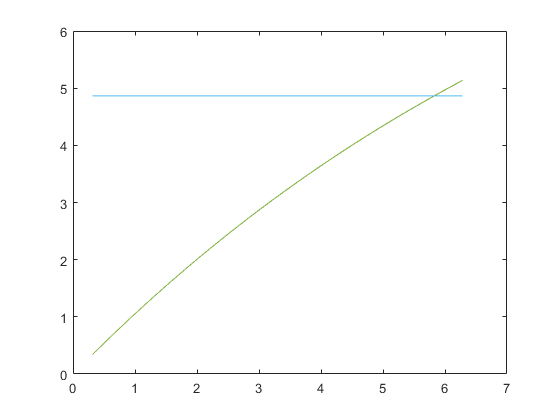


plot (Cla,CLa)
hold on
plot ([0.1*pi,2*pi],[CL/0.1047,CL/0.1047])
hold off

% SweepQuartC = 0:1:40; %Degrees

% for x=1:41
%     
%     SweepMaxT = atand(tand(SweepQuartC(x))-4/AR*((LocMaxT-0.25)*(1-TaperRatio)/(1+TaperRatio)))
%     
%     %Calc Zero Lift Drag
%     Re = AirDens*V*1.688*Cmac/DynVisc;
%     ReCut = 38.21*(Cmac/(2.08*10^(-5))); %Smooth Paint surface roughness
%     if ReCut < Re 
%         Cf = PerLamFlow*1.328/sqrt(Re)+(1-PerLamFlow)*0.455/((log10(ReCut)^2.58)*(1+0.144*(M)^2)^0.65);
%     else
%         Cf = PerLamFlow*1.328/sqrt(Re)+(1-PerLamFlow)*0.455/((log10(Re)^2.58)*(1+0.144*(M)^2)^0.65);
%     end
%     FF = (1+0.6*Tmax/LocMaxT+100*Tmax^4)*(1.34*M^(0.18)*(cosd(SweepMaxT)^(0.28))) 
%     Swet = (1.977+0.52*Tmax)*Sexp
%     CDo = Cf*FF*Q*Swet/S
% 
%     %Induced Drag Factor
%     Ne = 0; %Num of engines ON TOP of Wing
%     TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
%     K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC(x))^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)
%     
%     CD(x) = CDo + K*(W/(0.5*AirDens*V^2*S))^2
%     
% end
% 
% plot(SweepQuartC,CD)